Parameters

fc = 2000; %2kHz
fs = 44.1e3;

Text Encoding

text = ['hello world, vicky was in the musical. ' ...
    'Yichen does not wear glasses' ...
    'Yichen smushed matlab' ...
    'turns out implementation is hard' ...
    'Vicky is happy she is a software engineering'...
    'Yichen is suprised by Vickys career choise'];

text_bin = dec2bin(double(text));
s = size(text_bin);
bin_str = reshape(text_bin.'-'0',1,[]);
% a = [];
% for c=1:length(bin_str)
%     append(a, str2double(bin_str(c)));
% end

Pulse Shaping

%pulse = (sqrt(2)*cos(2*pi*fc*time)).* bin_str;

Transmit

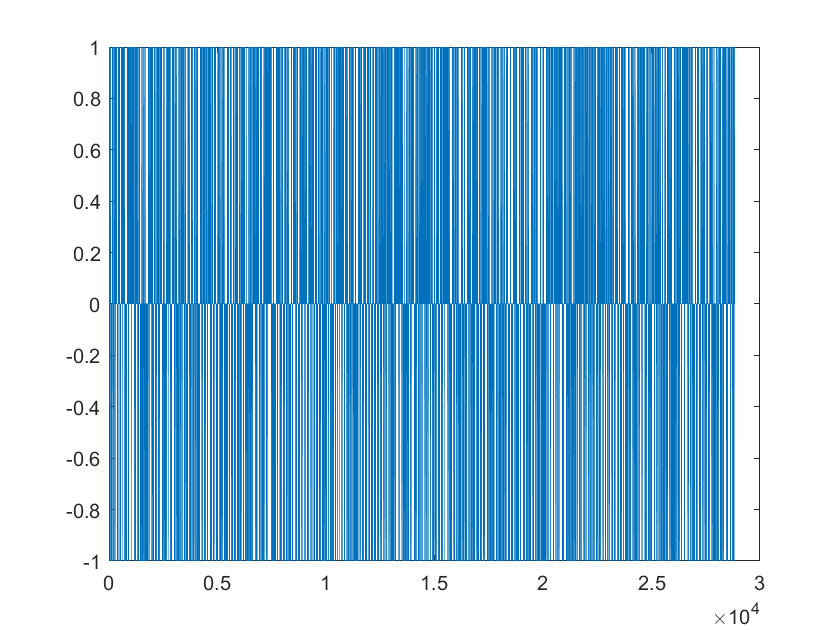

bin_str = 2 * bin_str - 1;
bin_str_us = upsample(bin_str, 20);
plot(bin_str_us);

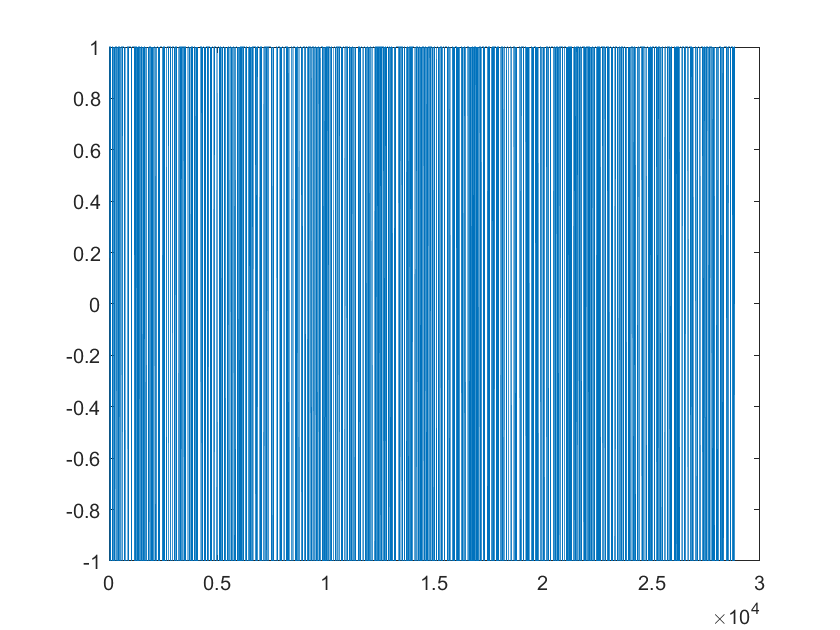

pulse = ones(20, 1);
X_I = conv(bin_str_us, pulse);
plot(X_I);

time = [0:length(X_I)-1]*1/fs;  %update to the length of the binary string
X = X_I .* cos(2*pi*fc*time) % then play this on the computer with sound

X =     1.0000    0.9597    0.8420    0.6563    0.4178    0.1455   -0.1385   -0.4113   -0.6509   -0.8381   -0.9576   -1.0000   -0.9617   -0.8458   -0.6617   -0.4242   -0.1526    0.1314    0.4048    0.6455    0.8342    0.9556    0.9999    0.9636    0.8496    0.6670    0.4307    0.1596   -0.1243   -0.3983   -0.6401   -0.8302   -0.9534   -0.9998   -0.9655   -0.8533   -0.6723   -0.4371   -0.1666    0.1173   -0.3917   -0.6346   -0.8262   -0.9513   -0.9996   -0.9673   -0.8570   -0.6776   -0.4435   -0.1736


%n = randn(1000,1);
sound(X, fs, 8);